## Experiment Name and Patient specification

ExperimentName = "Exp2_SVM_ANOVA_BayesianOptimization";

%Variables that vary per patient allowing quick interchanging
PatientID = "P10";
ChosenTableString = "IPDTable"; 

%Feature selection
startingNumberofFeatures = 1; 
stepsize = 1; 
totalNumberofFeatures = 1; 

numFeaturesToKeep = 10; %Features that will determine cross-validation results

 
%Makes the file for storing all the required information for the specific
%experiemnt.
if ispc
        % For Windows
        folderPath = fullfile(sprintf('..\\OwnResults\\%sRH\\%s',PatientID,ExperimentName));
        
        % Check if the folder exists; if not, create it
        if ~exist(folderPath, 'dir')
            mkdir(folderPath);
        end
    

    elseif ismac
        folderPath = fullfile(sprintf('../OwnResults/%sRH/%s',PatientID,ExperimentName));
        
        % Check if the folder exists; if not, create it
        if ~exist(folderPath, 'dir')
            mkdir(folderPath);
        end
    
end

## Generate all the IDP and PLV value if required

% Define PatientIDs
PatientID = char(PatientID);

PatientID = 'P10'

PatientIDs = {PatientID}; 

% Define the base folder path where results are stored
baseFolderPath = fullfile('..', 'OwnResults');

% Flag to check if processing is needed
processNeeded = false;

% Loop through each patient to check if their files exist
for i = 1:length(PatientIDs)
    PatientID = PatientIDs{i};
    
    % Define the patient-specific folder path
    patientFolderPath = fullfile(baseFolderPath, [PatientID 'RH'], 'MatlabGeneratedData');
    
    % Define filenames for the .mat files
    IPDMatFile = fullfile(patientFolderPath, 'IPDTable.mat');
    PLVMatFile = fullfile(patientFolderPath, 'PLVTable.mat');
    IPD_PLVMatFile = fullfile(patientFolderPath, 'IPD_PLVTable.mat');
    
    % Check if all required files exist for this patient
    if exist(IPDMatFile, 'file') && exist(PLVMatFile, 'file') && exist(IPD_PLVMatFile, 'file')
        % Prompt the user for input if files exist
        promptMessage = sprintf('Files for patient %s already exist.\nWould you like to skip generation? (yes/no): ', PatientID);
        userResponse = input(promptMessage, 's');
        
        if strcmpi(userResponse, 'yes')
            disp(['Skipping generation for patient ' PatientID '.']);
            continue;  % Skip to the next patient
        elseif strcmpi(userResponse, 'no')
            processNeeded = true;
            break;  % No need to check further, regenerate the files
        else
            disp('Invalid input. Please enter "yes" or "no".');
            i = i - 1;  % Ask the question again for the same patient
            continue;
        end
    else
        processNeeded = true;
        break;  % Files are missing, so processing is needed
    end
end

% Call GenerateIPD_PLVTables only if processing is needed
if processNeeded
    GenerateIPD_PLVTables(PatientIDs);
else
    disp('All required files already exist and were skipped as per user input.');
end

    {'Fz-FC3'}    {'Fz-FC1'}    {'Fz-FCz'}    {'Fz-FC2'}    {'Fz-FC4'}    {'Fz-C3'}    {'Fz-C1'}    {'Fz-C2'}    {'Fz-C4'}    {'Fz-CP3'}    {'Fz-CP1'}    {'Fz-CPz'}    {'Fz-CP2'}    {'Fz-CP4'}    {'FC3-FC1'}    {'FC3-FCz'}    {'FC3-FC2'}    {'FC3-FC4'}    {'FC3-C3'}    {'FC3-C1'}    {'FC3-C2'}    {'FC3-C4'}    {'FC3-CP3'}    {'FC3-CP1'}    {'FC3-CPz'}    {'FC3-CP2'}    {'FC3-CP4'}    {'FC1-FCz'}    {'FC1-FC2'}    {'FC1-FC4'}    {'FC1-C3'}    {'FC1-C1'}    {'FC1-C2'}    {'FC1-C4'}    {'FC1-CP3'}    {'FC1-CP1'}    {'FC1-CPz'}    {'FC1-CP2'}    {'FC1-CP4'}    {'FCz-FC2'}    {'FCz-FC4'}    {'FCz-C3'}    {'FCz-C1'}    {'FCz-C2'}    {'FCz-C4'}    {'FCz-CP3'}    {'FCz-CP1'}    {'FCz-CPz'}    {'FCz-CP2'}    {'FCz-CP4'}    {'FC2-FC4'}    {'FC2-C3'}    {'FC2-C1'}    {'FC2-C2'}    {'FC2-C4'}    {'FC2-CP3'}    {'FC2-CP1'}    {'FC2-CPz'}    {'FC2-CP2'}    {'FC2-CP4'}    {'FC4-C3'}    {'FC4-C1'}    {'FC4-C2'}    {'FC4-C4'}    {'FC4-CP3'}    {'FC4-CP1'}    {'FC4-CPz'}    {'FC4-CP2'}    {'FC4-CP4'}   

Some menu items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "ICLabel" v1.6 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.4 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.8 (see >> help eegplugin_firfilt)


pop_loadset(): loading file /Users/muaawiyah/Desktop/Investigation/OwnData/P10RH/P10RH_epochs_filt2_ICAEOG_ERDS.set ...
Reading float file '/Users/muaawiyah/Desktop/Investigation/OwnData/P10RH/P10RH_epochs_filt2_ICAEOG_ERDS.fdt'...
Scaling components to RMS microvolt
Scaling components to RMS microvolt
Creating a new ALLEEG dataset 1
Removing 100 trial(s)...
Pop_select: removing 405 unreferenced events
Scaling components to RMS microvolt
Scaling components to RMS microvolt
Scaling components to RMS microvolt
Scaling components to RMS microvolt
Scaling components to RMS microvolt
Creating a new ALLEEG dataset 2
Scaling components to RMS microvolt
channel or IC number: 1
channel or IC number: 2
channel or IC number: 3
channel or IC number: 4
channel or IC number: 5
channel or IC number: 6
channel or IC number: 7
channel or IC number: 8
channel or IC number: 9
channel or IC number: 10
channel or IC nu

## Load a specific patients data to allow Classification learn to Use specific data 

if ispc
        % For Windows
        % Construct the file path using sprintf
        IPDTable = load(sprintf('..\\OwnResults\\%sRH\\MatlabGeneratedData\\IPDTable.mat', PatientID)).IPDTable;
        PLVTable = load(sprintf('..\\OwnResults\\%sRH\\MatlabGeneratedData\\PLVTable.mat', PatientID)).PLVTable;
        IPD_PLVTable = load(sprintf('..\\OwnResults\\%sRH\\MatlabGeneratedData\\IPD_PLVTable.mat', PatientID)).IPD_PLVTable;
    elseif ismac
        IPDTable = load(sprintf('../OwnResults/%sRH/MatlabGeneratedData/IPDTable.mat', PatientID)).IPDTable;
        PLVTable = load(sprintf('../OwnResults/%sRH/MatlabGeneratedData/PLVTable.mat', PatientID)).PLVTable;
        IPD_PLVTable = load(sprintf('../OwnResults/%sRH/MatlabGeneratedData/IPD_PLVTable.mat', PatientID)).IPD_PLVTable;
end

% Use a switch statement to match the table name and assign the correct table
switch ChosenTableString
    case 'IPDTable'
        ChosenTable = IPDTable; 
    case 'PLVTable'
        ChosenTable = PLVTable; 
    case 'IPD_PLVTable'
        ChosenTable = IPD_PLVTable; 
    otherwise
        error('Table name not recognized.');
end


## ANOVA one way but determining the best number of features for highest accuracy

   200     1



|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |        0.45 |     0.39123 |        0.45 |        0.45 |       1.2297 |       976.19 |
|    2 | Best   |        0.43 |     0.29182 |        0.43 |     0.43152 |     0.039643 |       3.1078 |
|    3 | Accept |        0.49 |     0.21616 |        0.43 |     0.43001 |      0.02562 |    0.0015149 |
|    4 | Accept |         0.5 |     0.26135 |        0.43 |     0.43001 |       92.644 |     0.014548 |
|    5 | Accept |        0.44 |     0.11677 |        0.43 |     0.43001 |      0.29133 |       16.719 |
|    6 | Accept |       0.465 |     0.10663 |        0.43 |     

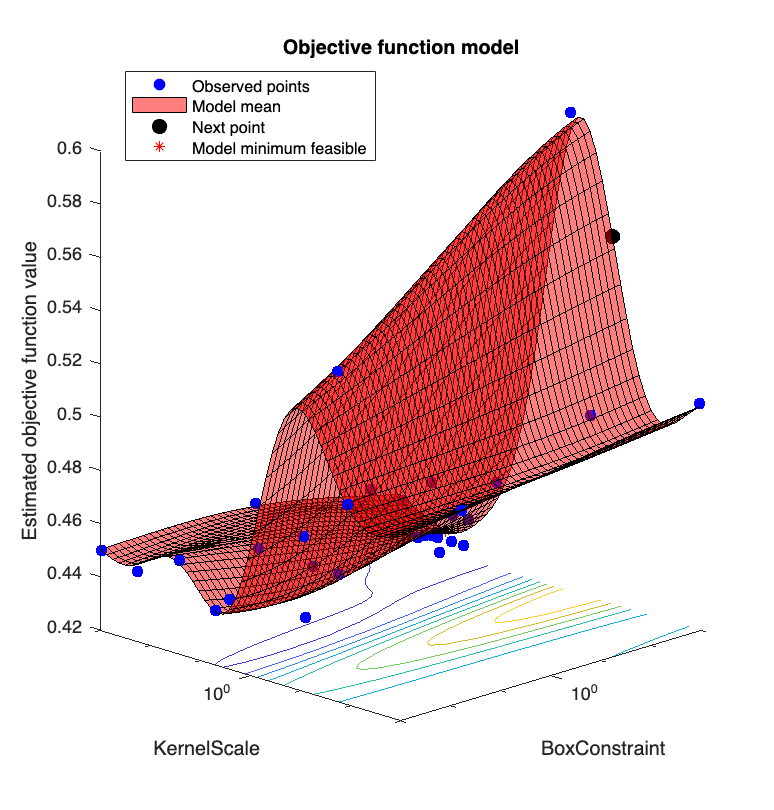

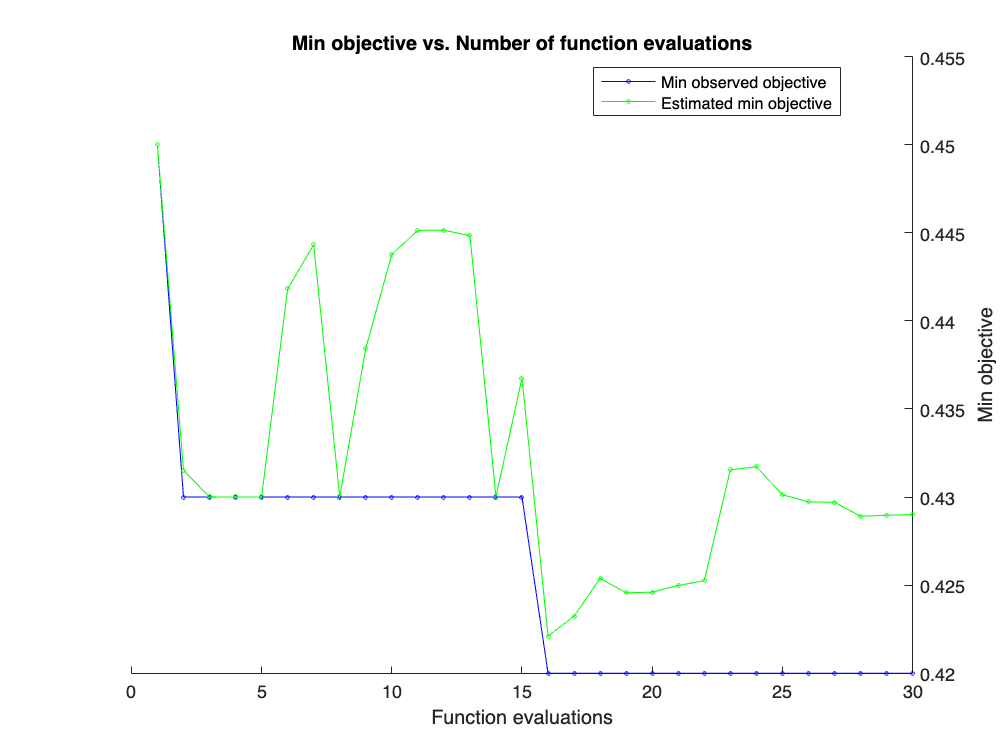


columnNames = ChosenTable.Properties.VariableNames;
predictorNames = columnNames(1,1:end-1);
isCategoricalPredictor = [false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false];


predictors = ChosenTable(:, predictorNames);
response = ChosenTable.Class;

predictors = standardizeMissing(predictors, {Inf, -Inf});
predictorMatrix = normalize(predictors);
newPredictorMatrix = zeros(size(predictorMatrix));

for i = 1:size(predictorMatrix, 2)
    if isCategoricalPredictor(i)
        newPredictorMatrix(:,i) = grp2idx(predictorMatrix{:,i});
    else
        newPredictorMatrix(:,i) = predictorMatrix{:,i};
    end
end
predictorMatrix = newPredictorMatrix;
responseVector = grp2idx(response);

% Rank features using ANOVA algorithm
for i = 1:size(predictorMatrix, 2)
    pValues(i) = anova1(...
        predictorMatrix(:,i), ...
        responseVector, ...
        'off');
end
[~,featureIndex] = sort(-log(pValues), 'descend');


%Generating the plot to determine the best number of features
accuracies = [];
numberofFeatures = []; 


for i = startingNumberofFeatures:stepsize:totalNumberofFeatures
    includedPredictorNames = predictors.Properties.VariableNames(featureIndex(1:i));
    iterationspredictors = predictors(:,includedPredictorNames);
    numberofFeatures = [numberofFeatures, i]; 

    disp(size(iterationspredictors))

    % Define the SVM model function for Bayesian Optimization
    svmModel = @(params)fitcsvm(iterationspredictors, response, ...
        'KernelFunction', 'rbf', ...
        'BoxConstraint', params.BoxConstraint, ...
        'KernelScale', params.KernelScale, ...
        'Standardize', true, ...
        'CrossVal', 'on', ...
        'KFold', 10);
    
    % Define the optimization variables
    optimVars = [
        optimizableVariable('BoxConstraint', [1e-3, 1e3], 'Transform', 'log');
        optimizableVariable('KernelScale', [1e-3, 1e3], 'Transform', 'log')
        ];
    
    % Define the objective function for Bayesian optimization
    minfn = @(params)kfoldLoss(svmModel(params));
    
    % Run Bayesian Optimization
    results = bayesopt(minfn, optimVars, ...
        'MaxObjectiveEvaluations', 30, ...
        'Verbose', 1, ...
        'IsObjectiveDeterministic', false, ...
        'AcquisitionFunctionName', 'expected-improvement-plus');
    
    % Extract the best hyperparameters
    bestParams = bestPoint(results);

    numFolds = 10; % Number of folds for cross-validation
    rng(1); % Fixed seed for consistent results
    
    % Use the full combined table for cross-validation
    xtrain = iterationspredictors;
    ytrain = response;
    cvPartition = cvpartition(ytrain, 'KFold', numFolds, 'Stratify', true);
    
    
    foldAccuracy = zeros(numFolds, 1);
    
    for fold = 1:numFolds
        trainIndices = cvPartition.training(fold);
        testIndices = cvPartition.test(fold);
    
        XtrainFold = xtrain(trainIndices, :);
        YtrainFold = ytrain(trainIndices);
        XtestFold = xtrain(testIndices, :);
        YtestFold = ytrain(testIndices);
    
        SVMModel = fitcsvm(XtrainFold, YtrainFold, ...
            'KernelFunction', 'rbf', ...
            'BoxConstraint', bestParams.BoxConstraint, ...
            'KernelScale', bestParams.KernelScale, ...
            'Standardize', true);
    
        YtestPred = predict(SVMModel, XtestFold);
    
        foldAccuracy(fold) = sum(YtestPred == YtestFold) / length(YtestFold);
    end

        accuracies = [accuracies, mean(foldAccuracy)];
end 

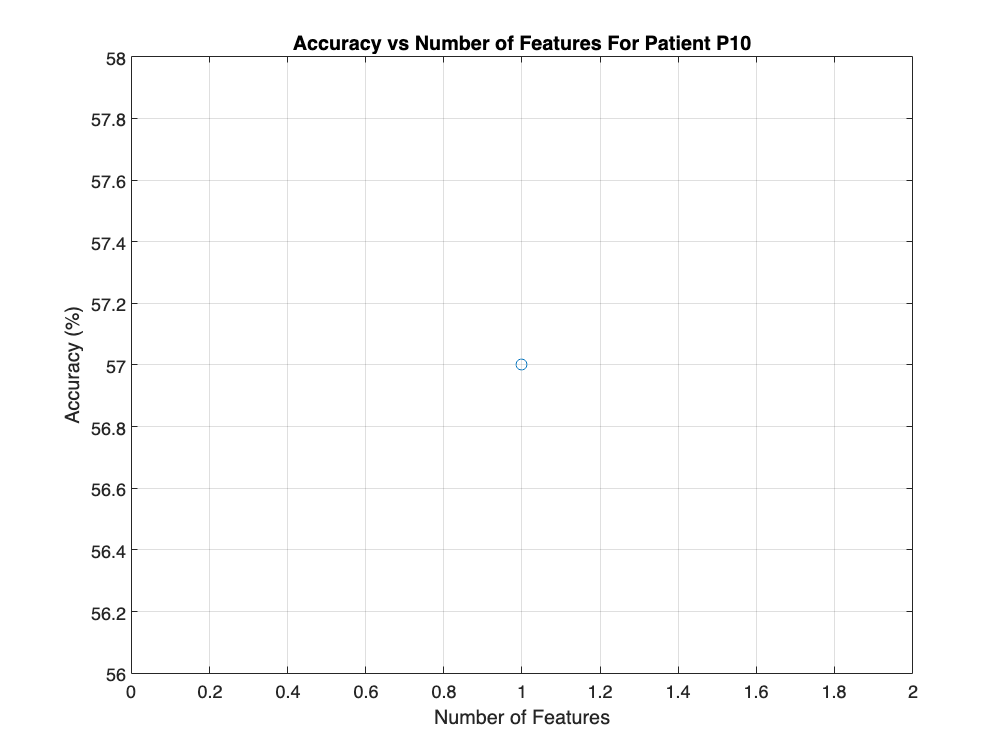


% Create the plot
figure; % Open a new figure window
plot(numberofFeatures, 100.*accuracies, '-o');
xlabel('Number of Features');
ylabel('Accuracy (%)');
title(sprintf('Accuracy vs Number of Features For Patient %s',PatientID));
grid on;

## Store the plot and its corresponding data 

%Required to store the accuracies and the number of features for the
%feature selection stage. 

% Define the path for Anova Feature Selection folder
anovaFolderPath = fullfile(folderPath, 'AnovaFeatureSelection');

anovaFolderPath = fullfile(anovaFolderPath,ChosenTableString);

% Check if the folder exists, if not, create it
if ~exist(anovaFolderPath, 'dir')
    mkdir(anovaFolderPath);
end

% Construct the filename using the specified format
fileName = sprintf('%s_%d_%d_%d.mat', ...
                   ChosenTableString,startingNumberofFeatures, stepsize, totalNumberofFeatures);

% Full path to save the .mat file in the AnovaFeatureSelection folder
fullFilePath = fullfile(anovaFolderPath, fileName);

% Construct the filename using the specified format
plotFileName = sprintf('%s_%d_%d_%d.fig', ...
                       ChosenTableString,startingNumberofFeatures, stepsize, totalNumberofFeatures);
plotFileNamePNG = sprintf('%s_%d_%d_%d.png', ...
                       ChosenTableString,startingNumberofFeatures, stepsize, totalNumberofFeatures);

% Full path to save the plot in the AnovaFeatureSelection folder
fullPlotPath = fullfile(anovaFolderPath, plotFileName);
fullPlotPathPNG = fullfile(anovaFolderPath, plotFileNamePNG);
% Save the accuracies and number of features to the .mat file
save(fullFilePath, 'accuracies', 'numberofFeatures');

% Save the plot with the constructed filename
saveas(gcf, fullPlotPath);
saveas(gcf, fullPlotPathPNG);

## Select ideal number of features

includedPredictorNames = predictors.Properties.VariableNames(featureIndex(1:numFeaturesToKeep));

includedPredictorNames = 1×10 cell array
    {'CP3-CPz-std'}    {'CP3-CPz-variance'}    {'C1-CP3-mean'}    {'C2-CP1-std'}    {'C2-CP1-variance'}    {'C1-CP1-std'}    {'C1-CP1-variance'}    {'C3-C1-mean'}    {'FC4-CP3-variance'}    {'FC4-CP1-variance'}




predictors = predictors(:,includedPredictorNames);


## Storing the Selected Features

storedPredictorNames = includedPredictorNames';


% Construct the filename using the specified format
fileName = sprintf('SelectedFeatures_%d.mat', ...
                   numFeaturesToKeep);

% Full path to save the .mat file in the AnovaFeatureSelection folder
fullFilePath = fullfile(anovaFolderPath, fileName);

% Save the arrays to the .mat file
save(fullFilePath, 'storedPredictorNames');

## Hyperparameter tuning

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |         0.5 |     0.14936 |         0.5 |         0.5 |      0.29686 |      0.11528 |
|    2 | Best   |        0.46 |     0.15416 |        0.46 |     0.46264 |      0.20185 |       772.15 |
|    3 | Best   |        0.45 |     0.40362 |        0.45 |     0.45236 |       308.27 |       6.1534 |
|    4 | Accept |         0.5 |     0.11495 |        0.45 |        0.45 |       369.75 |     0.017995 |
|    5 | Best   |       0.405 |     0.10321 |       0.405 |     0.40503 |       1.3729 |       33.605 |
|    6 | Accept |       0.445 |     0.10462 |       0.405 |     

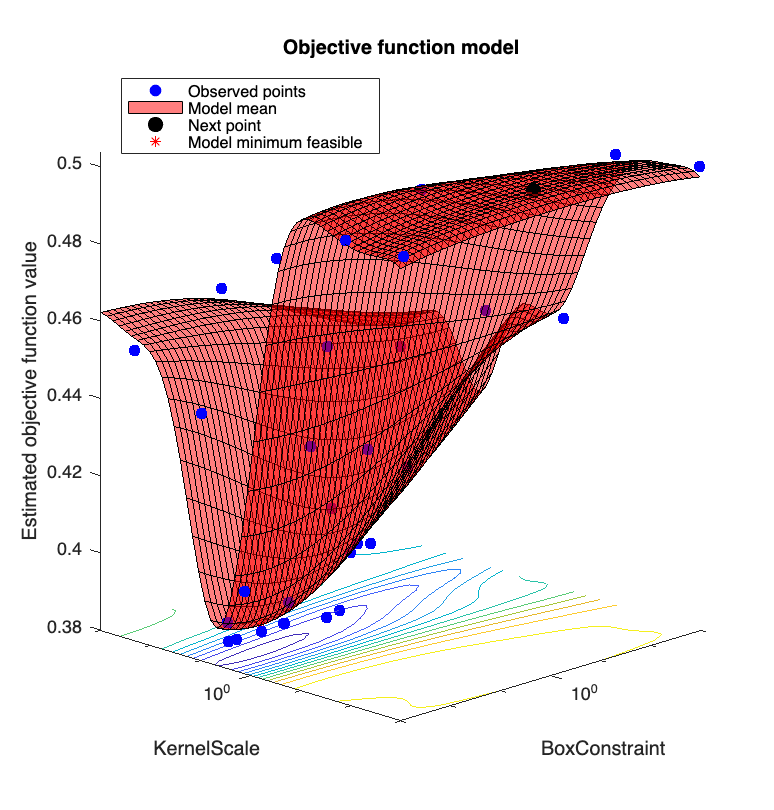

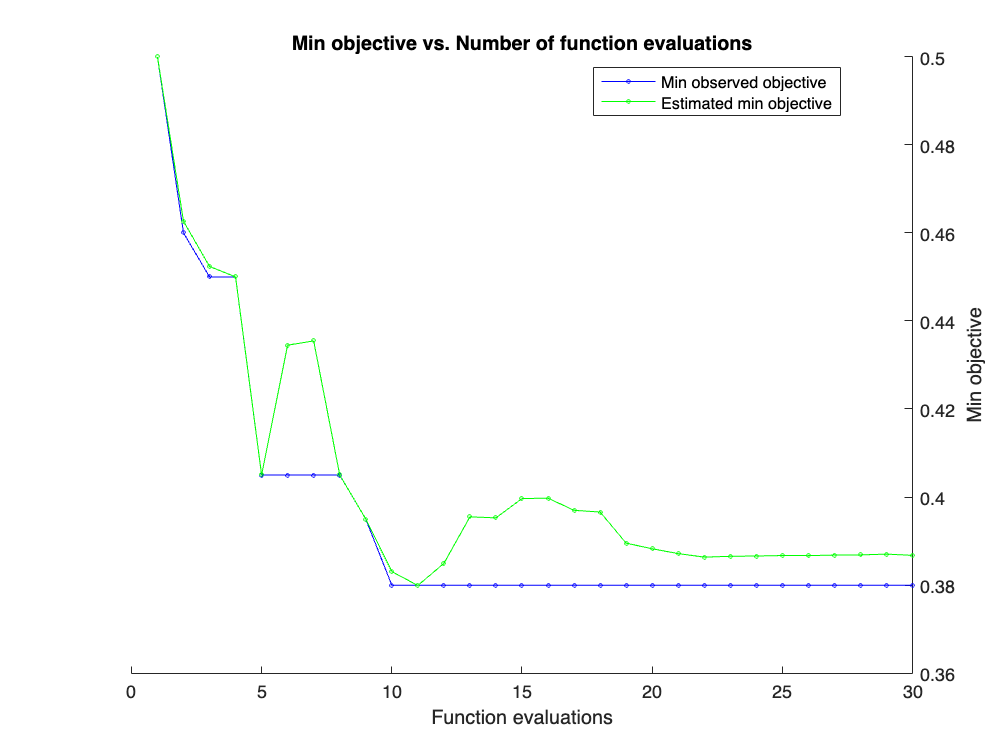

% Define the SVM model function for Bayesian Optimization
svmModel = @(params)fitcsvm(predictors, response, ...
    'KernelFunction', 'rbf', ...
    'BoxConstraint', params.BoxConstraint, ...
    'KernelScale', params.KernelScale, ...
    'Standardize', true, ...
    'CrossVal', 'on', ...
    'KFold', 10);

% Define the optimization variables
optimVars = [
    optimizableVariable('BoxConstraint', [1e-3, 1e3], 'Transform', 'log');
    optimizableVariable('KernelScale', [1e-3, 1e3], 'Transform', 'log')
    ];

% Define the objective function for Bayesian optimization
minfn = @(params)kfoldLoss(svmModel(params));

% Run Bayesian Optimization
results = bayesopt(minfn, optimVars, ...
    'MaxObjectiveEvaluations', 30, ...
    'Verbose', 1, ...
    'IsObjectiveDeterministic', false, ...
    'AcquisitionFunctionName', 'expected-improvement-plus');


% Extract the best hyperparameters
bestParams = bestPoint(results);

%box constraint = 991.6607
%kernel scale = 561.2574
%with 50 features for P3


## Store the hyperparameters 

% Define the path for Anova Feature Selection folder
hyperparametertuningFolderPath = fullfile(folderPath, 'HyperParameterTuning');


hyperparametertuningFolderPath = fullfile(hyperparametertuningFolderPath,ChosenTableString);


% Check if the folder exists, if not, create it
if ~exist(hyperparametertuningFolderPath, 'dir')
    mkdir(hyperparametertuningFolderPath);
end

% Construct the filename using the specified format
fileName = sprintf('%s_TunedParameters_%d.mat', ...
                   ChosenTableString,numFeaturesToKeep);

% Full path to save the .mat file in the AnovaFeatureSelection folder
fullFilePath = fullfile(hyperparametertuningFolderPath, fileName);

% Save the arrays to the .mat file
save(fullFilePath, 'bestParams');


## Stratified K-fold cross-validation

numFolds = 10; % Number of folds for cross-validation
rng(1); % Fixed seed for consistent results

% Use the full combined table for cross-validation
xtrain = predictors;
ytrain = response;
cvPartition = cvpartition(ytrain, 'KFold', numFolds, 'Stratify', true);


foldAccuracy = zeros(numFolds, 1);
foldPrecision = zeros(numFolds,1);
foldRecall = zeros(numFolds,1);
foldF1Score = zeros(numFolds,1); 

for fold = 1:numFolds
    trainIndices = cvPartition.training(fold);
    testIndices = cvPartition.test(fold);

    XtrainFold = xtrain(trainIndices, :);
    YtrainFold = ytrain(trainIndices);
    XtestFold = xtrain(testIndices, :);
    YtestFold = ytrain(testIndices);

    SVMModel = fitcsvm(XtrainFold, YtrainFold, ...
    'KernelFunction', 'rbf', ...
    'BoxConstraint', bestParams.BoxConstraint, ...
    'KernelScale', bestParams.KernelScale, ...
    'Standardize', true);

    YtestPred = predict(SVMModel, XtestFold);

    foldAccuracy(fold) = sum(YtestPred == YtestFold) / length(YtestFold);
    [foldPrecision(fold), foldRecall(fold), foldF1Score(fold)] = EvaluateModel(YtestPred,YtestFold);
end

meanAccuracy = mean(foldAccuracy);
disp(['Average Cross-Validation Accuracy: ', num2str(meanAccuracy * 100), '%']);

Average Cross-Validation Accuracy: 61%


disp(['Average Cross-Validation Precision: ', num2str(mean(foldPrecision) * 100), '%']);

Average Cross-Validation Precision: 62.175%


disp(['Average Cross-Validation Recall: ', num2str(mean(foldRecall) * 100), '%']);

Average Cross-Validation Recall: 61%


disp(['Average Cross-Validation F1-Score: ', num2str(mean(foldF1Score) * 100), '%']);

Average Cross-Validation F1-Score: 60.2052%


## Store the results of the stratified cross-validation

%Store the results of the stratified k-fold cross-validation 
stratifiedCrossValidationPath = fullfile(folderPath, 'Stratified_K-Fold_CrossValidation');

stratifiedCrossValidationPath = fullfile(stratifiedCrossValidationPath,ChosenTableString);

% Create a filename based on the feature selection parameters
filename = sprintf('%s_EvaluationMetrics_%d.mat',ChosenTableString,numFeaturesToKeep);

% Specify the path where you want to save the file
savePath = fullfile(stratifiedCrossValidationPath, filename);

% Check if the folder exists, if not, create it
if ~exist(stratifiedCrossValidationPath, 'dir')
    mkdir(stratifiedCrossValidationPath);
end

meanAccuracy = mean(foldAccuracy);
meanPrecision = mean(foldPrecision);
meanRecall = mean(foldRecall);
meanF1Score = mean(foldF1Score); 

% Save the arrays to the .mat file
save(savePath, 'foldAccuracy', 'foldPrecision', 'foldRecall', 'foldF1Score','meanAccuracy','meanPrecision','meanRecall','meanF1Score');
